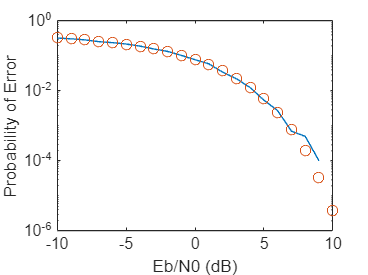

clear all
close all
clc
%rng(10)

%Parameters

tuid = [9,1,6,0,2,7,2,0,7];
A = tuid(9) + 2; % amplitude [Volts]
rb = 1000 * (tuid(8) + 3);       % Bit rate
Tb = 1/rb;      % Bit interval
fc = 20*rb;      % Carrier frequency
fs = 20*fc;    % Sampling frequency
Ts = 1/fs;      % Sampling interval
Ns = floor(Tb/Ts);  % Number of samples per bit
N = 10000;          % Number of bits to be transmitted

msg = randi([0,1],1,N);     % Message signal
[t,sig] = polar_nrz_6(msg,A,rb,fs);   % Polar non return to zero

carrier = A*cos(2*pi*fc*t);     % Carrier wave
psk = sig.*carrier;             % BPSK modulated signal

pulse = ones(1,Ns); % Reference pulse

EbN0db = -10:1:10;
error_rate = zeros([0,length(EbN0db)]);
error_rate_th = zeros([0,length(EbN0db)]);
for i=1:length(EbN0db)
    [error_rate(i), error_rate_th(i)] = calc_error(EbN0db(i) , Ns, psk, A, fc, pulse, t, msg, N);
end
figure(1)
semilogy(EbN0db, error_rate, EbN0db, error_rate_th, "o")
%plot(EbN0db, error_rate, EbN0db, error_rate_th, "o")

xlabel("Eb/N0 (dB)")
ylabel("Probability of Error")
saveas(1,'task1.png','png')

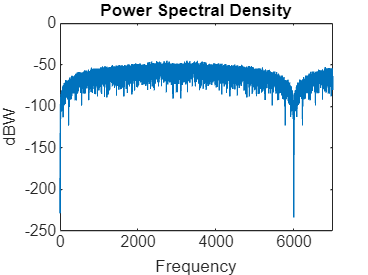

[f,psd]=myfft(psk,length(psk),2 * fs);
psd_dbw = 10*log10(psd);
figure(2)
plot(f(f>=0),psd_dbw(f>=0));
xlim([0,7000])
xlabel('Frequency')
ylabel('dBW')
title('Power Spectral Density')
saveas(2,'task2.png','png')

## Error Rate Function

function [BER,ber_th] = calc_error(EbN0_db, Ns, psk, A, fc, pulse, t, msg, N)
% Energy per bit to noise power spectral density ratio

EbN0 = 10.^(EbN0_db/10); % Converting to linear scale

Eb = Ns*sum(abs(psk).^2)/length(psk); % Signal energy per bit

N0 = Eb/EbN0;                % Noise power spectral density

n = sqrt(N0/2)*randn(1,length(psk)); % Generating Noise

received = psk+n; % Received signal

% Correlation decoding 

r_bb = A.*received.*cos(2*pi*fc*t);

dem = filter(pulse,1,r_bb); % Demodulated signal
dem = dem(Ns:Ns:end);       % Sampling at Tb
det = dem;                  % Detection
det(dem>=0)=1;
det(dem<0) = 0;
BER = sum(det~=msg)/N;

ber_th = qfunc(sqrt(2*EbN0));
end